clear all

# **ReadMe**:

This pipeline can extract balance parameters from the miniBESTest. It uses standing balance tasks on 1) one foot, 2) toe rise, 3) Rigid surface eyes open, and 4) Foam surface eyes close. 

You will need the **original excel** file exported from **MVN reader** to mark the estimate start and end point of the task. Plots will help you to validate the quality of the task.

# **Variable and Data Load**

**In this section you have to change necessary variables **and load the files and pathways. 

k = 1; %2       %1 is for the single leg and toe stand. 2 is for REO and FEC and incline stand
subject = 'HC01';                                                             !: TODO: CHANGE THIS PARAMETER
activity = 'MINIBEST';                                                        !: TODO: CHANGE THIS PARAMETER
excelfile = 'P2C_HC01-036.xlsx';                                              !: TODO: CHANGE THIS PARAMETER
base_path = 'Y:\P2C\P2C_Database_Segmented - Database paper version\Control'; !: TODO: CHANGE THIS PARAMETER
file_path = fullfile(base_path, subject, activity, excelfile);

%Creating pathway information of the segmented structure
structName = sprintf('%s_%s_Segmented.mat', subject, activity);
directorypath = fullfile(base_path, subject, activity);
structpath = fullfile(directorypath, structName);


sampling_rate = 60;
delta_t = 1/sampling_rate;

# **Data Segmentation**

This section will open the original excel file and you can make an structure and do segmentation for each task. 

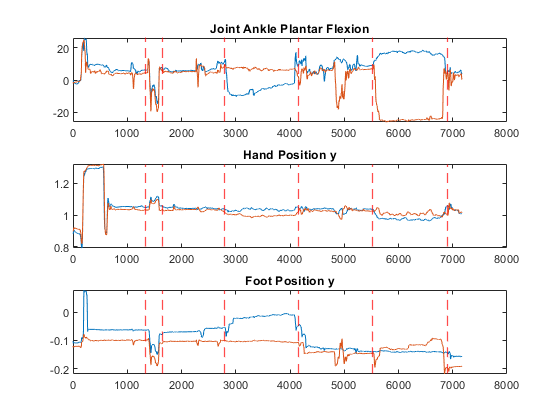

%Statement to load an existing structure or creating an empty strucutre
if isfile(structpath)
    loaded_data = load(structpath, '-mat'); % Load the .mat file
    if isfield(loaded_data, 'xsens_ord')
        xsens_ord = loaded_data.xsens_ord; % Extract the xsens_ord variable if it exists
    else
        xsens_ord = struct(); % Initialize if the file doesn't contain xsens_ord
    end
else
    xsens_ord = struct(); % Create an empty structure if file doesn't exist
end

xsens_ord = segmentation(file_path, xsens_ord, k);

save(structpath, 'xsens_ord');

%load the parameter labels
load('mbtParameters.mat');
ExportparametersMBT = array2table(nan(1, numel(mbtParameters)), 'VariableNames', mbtParameters);

# **Calculating Sway Area (mm^2/s), Mean Jerk RMS (m/s^3), and max plantar flexion (degrees)**

structnames = {'Toe', 'SingleLeftLeg', 'SingleRightLeg', 'Incline', 'REO', 'FEC'};
for i = 1:numel(structnames)
    close all;
    % Retrieve data for current struct
    joint_angles_x = xsens_ord.(structnames{i}).JointAnglesXZY(:, 52);
    joint_angles_y = xsens_ord.(structnames{i}).JointAnglesXZY(:, 64);
    segment_pos_hand_x = xsens_ord.(structnames{i}).SegmentPosition(:, 34);
    segment_pos_hand_y = xsens_ord.(structnames{i}).SegmentPosition(:, 46);
    segment_pos_foot_x = xsens_ord.(structnames{i}).SegmentPosition(:, 54);
    segment_pos_foot_y = xsens_ord.(structnames{i}).SegmentPosition(:, 66);
    center_of_mass_x = xsens_ord.(structnames{i}).CenterOfMass(:, 2);
    center_of_mass_y = xsens_ord.(structnames{i}).CenterOfMass(:, 3);
    center_of_mass_accx = xsens_ord.(structnames{i}).CenterOfMass(:, 8);
    center_of_mass_accy = xsens_ord.(structnames{i}).CenterOfMass(:, 9);

    % Initial figure plotting
    figure;
    % Subplot 1: Joint Angles
    subplot(3, 2, 1);
    plot(joint_angles_x);
    hold on;
    plot(joint_angles_y);
    title('Ankle Joint Angle Plantar Flexion');
    hold off;

    % Subplot 2: Hand Position
    subplot(3, 2, 2);
    plot(segment_pos_hand_x);
    hold on;
    plot(segment_pos_hand_y);
    title('Hand Position y');
    hold off;

    % Subplot 3: Foot Position
    subplot(3, 2, 3);
    plot(segment_pos_foot_x);
    hold on;
    plot(segment_pos_foot_y);
    title('Foot Position y');
    hold off;

    % Subplot 4: Center of Mass
    subplot(3, 2, [4, 5]);
    plot(center_of_mass_x, center_of_mass_y);
    title('Center of Mass');

    % Get trim points using ginput
    trimpoints = zeros(1, 2);
    for p = 1:2
        zoom off; pan off; % Disable zoom and pan
        [x, ~] = ginput(1);
        trimpoints(p) = round(x);

        % Update plots with xline for the first three subplots only
        % Subplot 1: Joint Angles
        subplot(3, 2, 1);
        hold on;
        xline(x, 'r--', 'LineWidth', 1);
        hold off;

        % Subplot 2: Hand Position
        subplot(3, 2, 2);
        hold on;
        xline(x, 'r--', 'LineWidth', 1);
        hold off;

        % Subplot 3: Foot Position
        subplot(3, 2, 3);
        hold on;
        xline(x, 'r--', 'LineWidth', 1);
        hold off;

        % Trim and replot the last subplot dynamically after the second ginput
        if p == 2
            trimpoints = sort(trimpoints);
            trimmed_indices = (1:length(center_of_mass_x) >= trimpoints(1)) & ...
                              (1:length(center_of_mass_x) <= trimpoints(2));
            center_of_mass_x_trimmed = center_of_mass_x(trimmed_indices);
            center_of_mass_y_trimmed = center_of_mass_y(trimmed_indices);

            subplot(3, 2, [4, 5]);
            cla; % Clear existing plot
            plot(center_of_mass_x_trimmed, center_of_mass_y_trimmed, 'b');
            title('Center of Mass (Trimmed)');
        end
    end

    fprintf('Press Enter to proceed to the next step...\n');
    pause;

    % Perform additional computations
    if i == 1
        ExportparametersMBT{1, 11} = abs(min(min(xsens_ord.(structnames{1}).JointAnglesXZY(:, 52)), min(xsens_ord.(structnames{1}).JointAnglesXZY(:, 64))));
    else
        center_of_mass_x = center_of_mass_x - mean(center_of_mass_x);
        center_of_mass_y = center_of_mass_y - mean(center_of_mass_y);

        % Calculate sway area
        total_area = 0;
        for k = 1:(length(center_of_mass_x) - 1)
            x1 = center_of_mass_x(k);
            y1 = center_of_mass_y(k);
            x2 = center_of_mass_x(k+1);
            y2 = center_of_mass_y(k+1);
            area = 0.5 * abs(x1 * y2 - x2 * y1);
            total_area = total_area + area;
        end
        total_duration = length(center_of_mass_x) / sampling_rate;
        sway_area_rate = total_area / total_duration;

        % Calculate jerk RMS
        jerk_x = diff(center_of_mass_accx) / delta_t;
        jerk_y = diff(center_of_mass_accy) / delta_t;
        jerk_magnitude = sqrt(jerk_x.^2 + jerk_y.^2);
        jerk_rms = sqrt(mean(jerk_magnitude.^2));

        % Update ExportparametersMBT
        ExportparametersMBT{1, ((2 * i) - 2)} = jerk_rms;
        ExportparametersMBT{1, ((2 * i) - 3)} = sway_area_rate;
    end
end

Press Enter to proceed to the next step...


Error using ginput (line 84)
Interrupted by figure deletion

labels = ExportparametersMBT.Properties.VariableNames';
data = ExportparametersMBT{1, :}'; 
transposedData = table(labels, data, 'VariableNames', {'Parameter', 'Value'});
filename = fullfile(directorypath, [subject '_' activity '_Exportparameters.csv']);
writetable(transposedData, filename);
